clearvars
clear

syms s(t) v(t)

s(t) = 2.4*t - 4.9*t^2

$$s(t) = \frac{12\,t}{5}-\frac{49\,t^{2}}{10}$$


v(t) = diff(s,t)

$$v(t) = \frac{12}{5}-\frac{49\,t}{5}$$

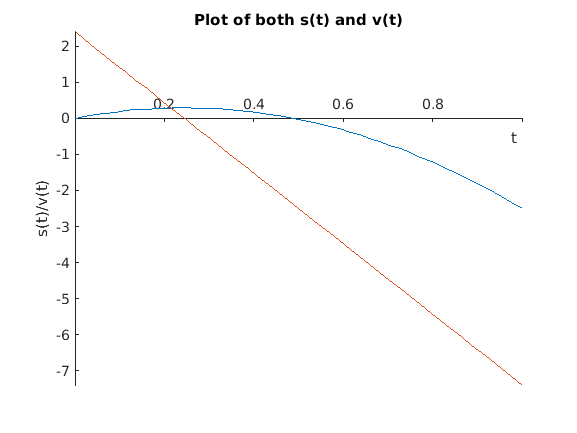


fplot(s, [0 1])

hold on %ensures second plot command is continued on same graph

fplot(v, [0 1])

hold off

%beautifying
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

xlabel("t")
ylabel("s(t)/v(t)")
title("Plot of both s(t) and v(t)")

clearvars

syms C(f) gra(f)

C(f) = 5*exp(-0.5*f) + 0.6*f

$$C(f) = \frac{3\,f}{5}+5\,{\mathrm{e}}^{-\frac{f}{2}}$$


gra(f) = diff(C,f)

$$gra(f) = \frac{3}{5}-\frac{5\,{\mathrm{e}}^{-\frac{f}{2}}}{2}$$

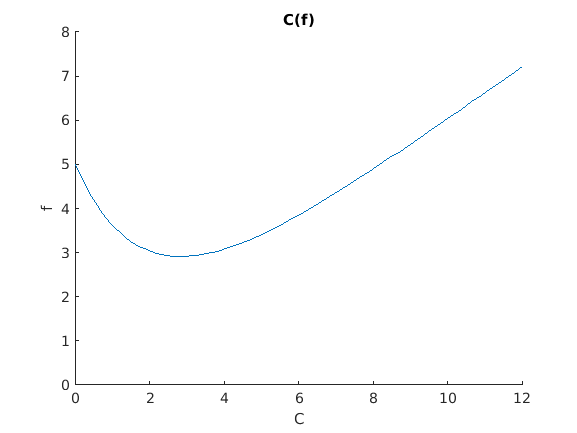


fplot(C, [0 12])
ylim([0 8]) %forcing Y limit to be more helpful

%beautifying
ax=gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

xlabel("C")
ylabel("f")
title("C(f)")


%solving for the minima
solve(gra(f)==0,f)

$$ans = -2\,\log\left(\frac{6}{25}\right)$$

eval(ans)

ans = 2.8542

clearvars

syms t(w) t_2(w) t_3(w)

t(w) = -0.0016*w^3 + 0.17*w^2 - 3.4*w + 250;

t_2(w) = diff(t,w);

solve(t_2==0,w); %finding turning points
eval(ans)

ans =    12.0499
   58.7835



%using second derivative test to check if the turning points are maxima or
%minima

t_3(w) = diff(t_2,w);

%this result shows a minima
eval(t_3(12.05))

ans = 0.2243

eval(t(12.05))

ans = 230.9149


%result indicates a maxima
eval(t_3(58.78))

ans = -0.2243

eval(t(58.78))

ans = 312.5689

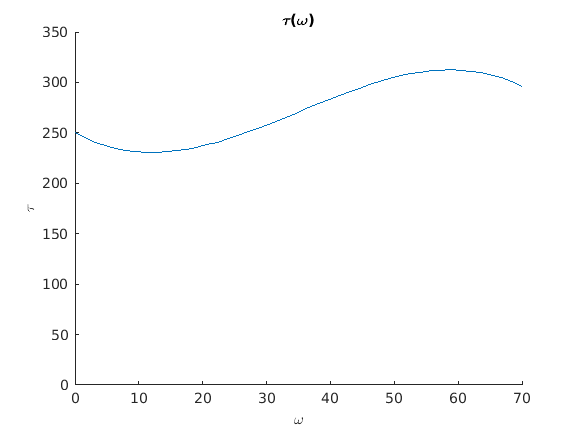


%plotting to check if the results are correct
fplot(t, [0 70])
ylim([0 350])

%beautifying
ax=gca;
ax.XAxisLocation ="origin";
ax.YAxisLocation ="origin";
box off
title("\tau(\omega)")
ylabel("\tau")
xlabel("\omega")